# BIV Whirlpool-Galaxie Processing

Setup

dark_frame_file = "darkframe.tiff"

dark_frame_file = "darkframe.tiff"

background_file = "background_fit.tiff"

background_file = "background_fit.tiff"

raw_files = dir("raw/*.tiff")

raw_files = 108×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



addpath('code');

Load darkframe and background

dark_frame = im2double(imread(dark_frame_file));
dark_frame = crop_to_match(dark_frame,background);

background = im2double(imread(background_file));

Load raw images and subtract darkframe and background

raw_images = {};
for k = 1:numel(raw_files)
    img = im2double(imread(fullfile("raw/", raw_files(k).name)));
    img = crop_to_match(img,background); % Crop images since background is slightly smaller
    img_calibrated = img - dark_frame - background;

    img_calibrated(img_clean < 0) = 0; % Clip negatives

    raw_images{end+1} = img_calibrated;
end

Reference image

reference = raw_images{1}

reference =     0.0094    0.0139    0.0136    0.0116    0.0164    0.0146    0.0090    0.0113    0.0126    0.0123    0.0175    0.0082    0.0256    0.0054    0.0176    0.0141    0.0138    0.0132    0.0084    0.0159    0.0181    0.0126    0.0116    0.0152    0.0103    0.0216    0.0143    0.0161    0.0181    0.0163    0.0112    0.0131    0.0143    0.0137    0.0218    0.0076    0.0186    0.0163    0.0215    0.0186    0.0148    0.0241    0.0199    0.0121    0.0079    0.0196    0.0092    0.0163    0.0111    0.0177
    0.0164    0.0143    0.0152    0.0183    0.0143    0.0083    0.0230    0.0127    0.0202    0.0066    0.0191    0.0159    0.0122    0.0157    0.0133    0.0175    0.0182    0.0168    0.0170    0.0108    0.0076    0.0057    0.0126    0.0060    0.0199    0.0081    0.0188    0.0126    0.0135    0.0033    0.0117    0.0181    0.0146    0.0095    0.0104    0.0047    0.0087    0.0083    0.0079    0.0126    0.0131    0.0166    0.0195    0.0135    0.0037    0.0108    0.0163    0.0074    0.0

Align images to reference

aligned_images = cell(size(rawImages));
aligned_images{1} = reference;

n = numel(rawImages);
h = waitbar(0, 'Aligning images...');

for k = 2:n
    moving_image = rawImages{k};
    
    % Detect stars
    points_fixed  = get_star_tracking_points(reference);
    points_moving = get_star_tracking_points(moving_image);

    [points_fixed, points_moving] = match_points(points_fixed, points_moving);
    
    % Find transform
    tform = estimateGeometricTransform2D(points_fixed, points_moving, 'similarity');
    
    % Warp image
    output_view = imref2d(size(reference));
    aligned = imwarp(moving_image, tform, "OutputView", output_view);
    
    aligned_images{k} = aligned;

    waitbar(k/n, h, sprintf('Aligned %d of %d images', k, n));
end

close(h);

Stack images

stack_sum = zeros(size(reference));
for k = 1:numel(aligned_images)
    stack_sum = stack_sum + aligned_images{k};
end
stack_mean = stack_sum/n;

Background Correction

Save

save_image(img_clean, "output.tif");

Crop

margin_from_edge = 20

margin_from_edge = 20

cropped = circular_crop(img_clean, margin_from_edge);

Display

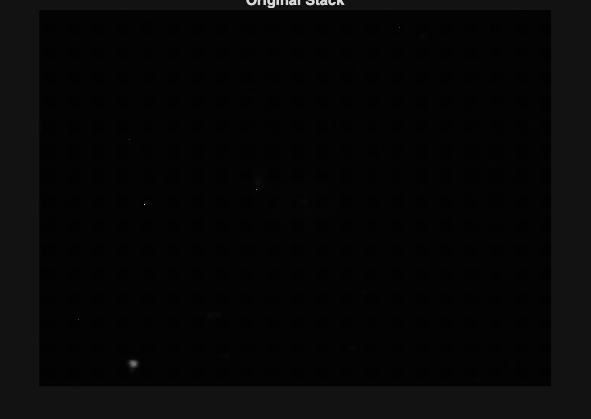

figure; imshow(stack_mean, []); title('Original Stack');

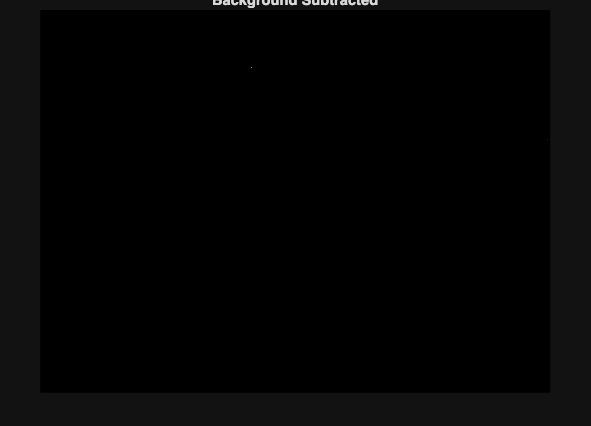

figure; imshow(img_clean, []); title('Background Subtracted');

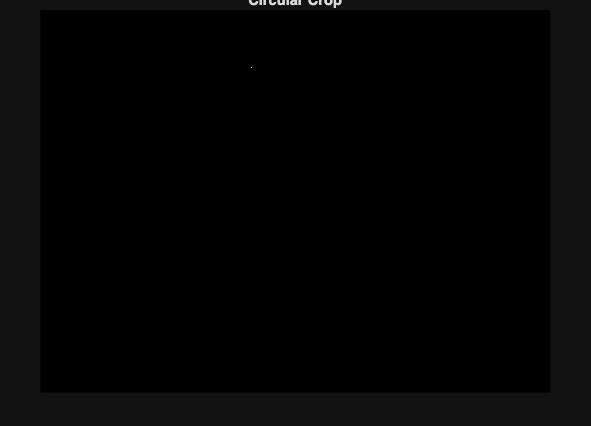

figure; imshow(cropped, []); title('Circular Crop');

PostProcess

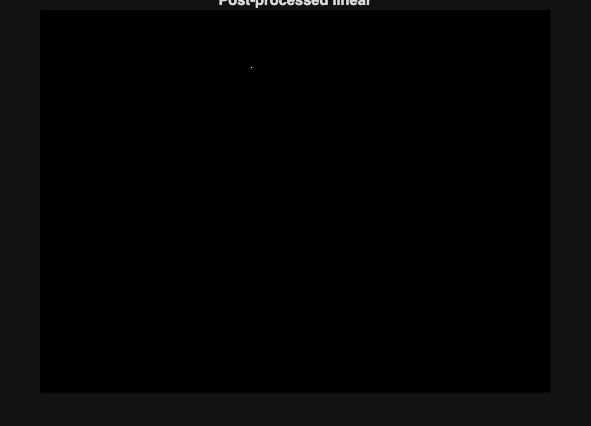

% robust normalization
low = prctile(cropped(:), 1);   % ignore lowest 1%
high = prctile(cropped(:), 99); % ignore highest 1%

img_norm = (cropped - low) / (high - low);
img_norm(img_norm < 0) = 0;
img_norm(img_norm > 1) = 1;

% adaptive histogram equalization (CLAHE) with clipping
img_adap = adapthisteq(cropped);


img_smooth = imgaussfilt(img_adap, 0.5);  % sigma = 0.5-1 pixel

% save
save_image(img_smooth, "output.tif");

% display
figure; imshow(img_adap, []); title('Post-processed linear');

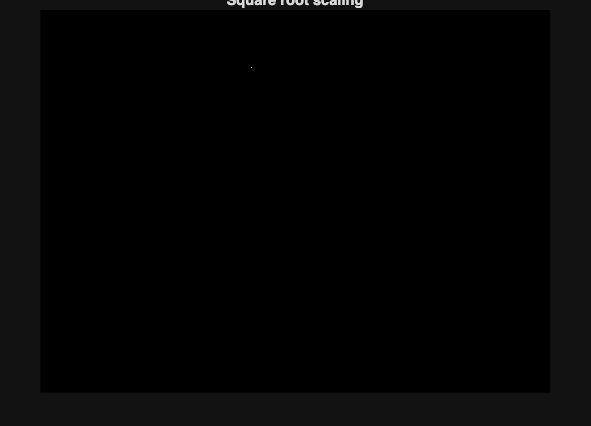

figure; imshow(cropped, []); title('Square root scaling');

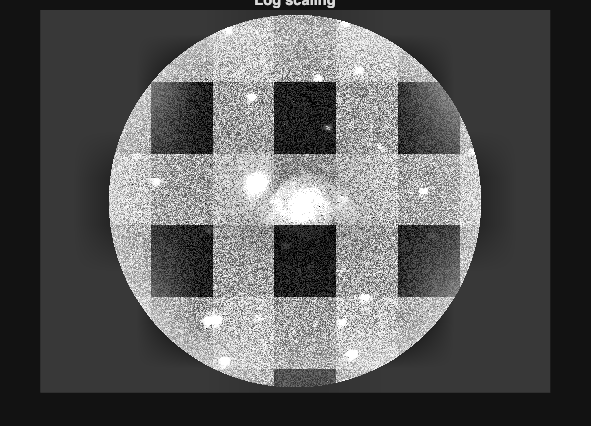

figure; imshow(log(1 + img_final), []); title('Log scaling');